Part 1:

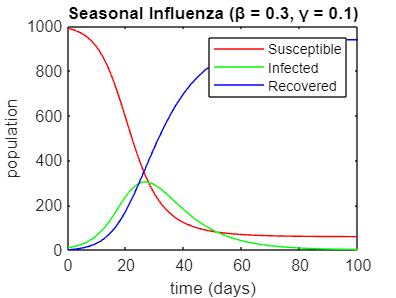

h = 1;
S0 = 990;
I0 = 10;
R0 = 0;
T0 = 0;
T = 100;

%influenza, COVID-19, Measeles
beta = [0.3,1,2]; 
gamma = [0.1,0.1,0.2];



influenza = modelSIR(S0,I0,R0,T0,T,h,beta(1),gamma(1));
COVID = modelSIR(S0,I0,R0,T0,T,h,beta(2),gamma(2));
measles = modelSIR(S0,I0,R0,T0,T,h,beta(3),gamma(3));


plot(influenza(1,:),influenza(2,:),'r',influenza(1,:),influenza(3,:),'g',influenza(1,:),influenza(4,:),'b')
xlabel('time (days)');
ylabel('population');
legend('Susceptible','Infected','Recovered');
title('Seasonal Influenza (β = 0.3, γ = 0.1)');

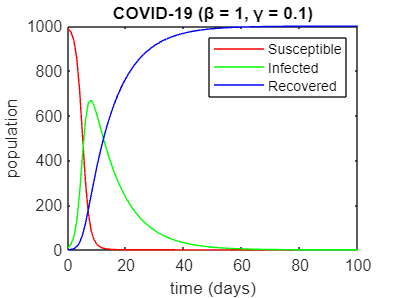


plot(COVID(1,:),COVID(2,:),'r',COVID(1,:),COVID(3,:),'g',COVID(1,:),COVID(4,:),'b')
xlabel('time (days)');
ylabel('population');
legend('Susceptible','Infected','Recovered');
title('COVID-19 (β = 1, γ = 0.1)');

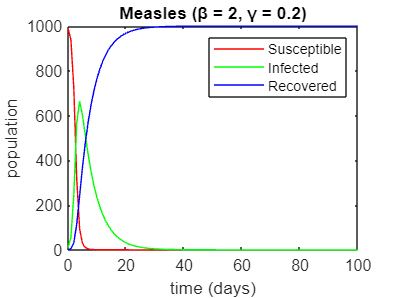


plot(measles(1,:),measles(2,:),'r',measles(1,:),measles(3,:),'g',measles(1,:),measles(4,:),'b')
xlabel('time (days)');
ylabel('population');
legend('Susceptible','Infected','Recovered');
title('Measles (β = 2, γ = 0.2)');